对输出电压的拟合

导入汇总的表格

dy = importfile('Dynamic_modeling_result.csv', 2, 1577);


绘图

单独对autoformer进行降采样处理，让图好看

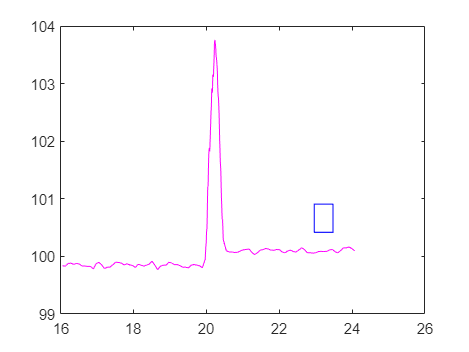

autotime1 = dy.Var1(1:767);
autotime2 = dy.Var1(768:862);
autotime3 = dy.Var1(863:1576);
%对应autoformer的值
autoV1 =  dy.Var6(1:767);
autoV2 =  dy.Var6(768:862);
autoV3 =  dy.Var6(863:1576);
%降采样两端的数值
n = 15; % downsampling factor
autotime1n = downsample(autotime1,n);
autoV1n = downsample(autoV1,n);
autotime3n = downsample(autotime3,n);
autoV3n = downsample(autoV3,n);
%重组
autotime = [autotime1n;autotime2;autotime3n];
autoV = [autoV1n;autoV2;autoV3n];
figure(1)
plot(autotime,autoV,'Color',[1 0 1],'MarkerSize',1.5);%autoformer，紫色)
%绘制蓝色的框

annotation('rectangle',[0.67,0.34,0.04,0.08],'LineStyle','-','Color','b','LineWidth',0.7);
% hold on 
% plot(dy.Var1,dy.Var6,'Color',[1 0 0],'MarkerSize',1.5);%autoformer，紫色


单独对reformer进行降采样处理，让图好看

retime1 = dy.Var1(1:762);
retime2 = dy.Var1(763:797);
retime3 = dy.Var1(798:1576);
%对应autoformer的值
reV1 =  dy.Var7(1:762);
reV2 =  dy.Var7(763:797);
reV3 =  dy.Var7(798:1576);
%降采样两端的数值
n = 25; % downsampling factor
m = 4;
h = 23;
retime1n = downsample(retime1,n);
reV1n = downsample(reV1,n);
retime2n = downsample(retime2,m);
reV2n = downsample(reV2,m);
retime3n = downsample(retime3,h);
reV3n = downsample(reV3,h);
%重组
retime = [retime1n;retime2n;retime3n];
reV = [reV1n;reV2n;reV3n];
figure(1)
plot(retime,reV,'*','Color',[1 0 1],'MarkerSize',1.5);%reformer，紫色)
% hold on 
% plot(dy.Var1,dy.Var6,'Color',[1 0 0],'MarkerSize',1.5);%reformer，紫色

t = tiledlayout('flow','TileSpacing','tight');
set (gcf,'Position',[680 200 560 600]);
%left bottom可以去掉白边
set(gca,'FontName','Times New Roman','FontSize',10);
ax1 = nexttile;
plot(dy.Var1,dy.Var3,'LineWidth',2,'Color',[0 0 0]);%原始信号黑色
set(gca,'FontName','Times New Roman','FontSize',10);
%gca表示当前对象句柄
%axis([16 24.2 99.5 104]); %限制坐标区间的范围，可以限制不同图的坐标
%局部分放大
axis([20 20.4 102.4 103.4]);
hold on
%'--','LineWidth',1.2,'Color',[1 0 0],'MarkerSize',2)
plot(autotime,autoV,'s','Color',[1 0 1],'MarkerSize',5);%autoformer，紫色
plot(dy.Var1,dy.Var5,'linewidth',1.5,'Color',[0 0 1]);%informer;蓝色
plot(retime,reV,'*','Color',[0 0 1],'MarkerSize',5);%reformer深蓝山
plot(dy.Var1,dy.Var8,'-.','linewidth',1.5,'color',[0.717647058823529 0.274509803921569 1])%trans橘色
plot(dy.Var1,dy.Var9,'--','linewidth',1.5,'color',[0,0.5,0])  %wcnn绿);
plot(dy.Var1,dy.Var10,':','linewidth',1.8,'color',[0.93,0.69,0.13])%lstm浅黄色
plot(dy.Var1,dy.Var11,'-.','linewidth',1.5,'color',[0.85,0.33,0.10]) %redu橙色
plot(dy.Var1,dy.Var12,'-','linewidth',1.5,'color',[0.06,1.00,1.00]); % 离散亮蓝色
plot(dy.Var1,dy.Var13,':','linewidth',1.8,'color',[0.00,0.45,0.74]); % GAM；
plot(dy.Var1,dy.Var4,'LineWidth',1.5,'Color',[1 0 0]);%effinformer 红色;
hold off 
xlabel({'Time(ms)'},'FontName','Times New Roman','FontSize',12);
ylabel('Voltage (V)','FontName','Times New Roman','FontSize',12);
grid on;

增加图例为第二幅图

lgd = legend('Simu-avg','Autoformer','Informer','Reformer','Transformer', ...
    'WCNN','LSTM','Redu-order','Discrete','GAM','Effinformer','NumColumns',3, ...
    'FontName','Times New Roman','FontSize',11);
set(lgd,'Position',[-0.0101895063446953 0.8446666669706503 0.650689506344695 0.081999996960163]);
         
%[Positionleft, bottom, width, height]
lgd.Layout.Tile = 2;
lgd.Layout.Tile = 'north'; %控制变量是'north'